## A: Now, with drive+LDE

### A1. Prepair parameters for drive simulation

First figure out orientation domains

ODNum = 4; % 4 orientation domains
% A function from Neuron Ind and spatial scales to Orientation Domains
OD_S = zeros(size(NnS.X),'single');
OD_SMap = zeros(n_S_HC*N_HC,'single');
for NeuInd = 1:length(NnS.X)
    OD_S(NeuInd) = OrientDom(ODNum,NnS.X(NeuInd),NnS.Y(NeuInd),n_S_HC);
    OD_SMap(NnS.Y(NeuInd),NnS.X(NeuInd)) = OD_S(NeuInd);
end

OD_C = zeros(size(NnC.X),'single');
OD_CMap = zeros(n_C_HC*N_HC,'single');
for NeuInd = 1:length(NnC.X)
    OD_C(NeuInd) = OrientDom(ODNum,NnC.X(NeuInd),NnC.Y(NeuInd),n_C_HC);
    OD_CMap(NnC.Y(NeuInd),NnC.X(NeuInd)) = OD_C(NeuInd);
end
OD_E = [OD_S, OD_C];

OD_I = zeros(size(NnI.X),'single');
OD_IMap = zeros(n_I_HC*N_HC,'single');
for NeuInd = 1:length(NnI.X)
    OD_I(NeuInd) = OrientDom(ODNum,NnI.X(NeuInd),NnI.Y(NeuInd),n_I_HC);
    OD_IMap(NnI.Y(NeuInd),NnI.X(NeuInd)) = OD_I(NeuInd);
end

### Incorporate Phase:

Use an updating vector for each E cell to reflect its on-off phase

Directly pull lgnEevents and do multiplication with the phase factor

StimulusFac = 1;
LGNFreq = 4; % 2 4 10Hz
tMod = 1e3/LGNFreq; MaxOnPhase = tMod/2;% Each Cycle lasts for 500 ms
PhaseE = single(tMod*rand(N_E,1));
PhaseFRS = [90 67.5 45 67.5,    0  22.5 45 22.5] *N_Slgn/1e3 * StimulusFac; % 4 to 5
%PhaseFRC = [90 67.5 45 67.5,    0  22.5 45 22.5] *N_Clgn/1e3 * StimulusFac;
PhaseFRC = 45*ones(1,8) *N_Clgn/1e3 * StimulusFac;
lambda_EOn_drive  = [PhaseFRS(OD_S),PhaseFRC(OD_C)]'; % Should do another for Cplx cells
lambda_EOff_drive = [PhaseFRS(OD_S+ODNum),PhaseFRC(OD_C+ODNum)]';
% T partition
T = 10000; dt = 0.1; TPar = 10;

LGN & L6 input classified by domains

Inputs are high now!!! Bernouli may underestimate, and we need to use:

- first simulate Poisson processes

- Feed them to the new function

%DriveE = [60,53,48,53]*4/1e3; % Ordered by domains, times the number of lgn cells, normalized by 1000ms
lambda_E_drive_Pre = 45 *N_Slgn/1e3 * StimulusFac;
lambda_I_drive_Pre = 45 *N_Ilgn/1e3 * StimulusFac;

% Ver1
% L6Ord_F = [50 33 15 33];
% Ver 4
L6Ord_F = [50 31 12 31];
L6S_Drive = L6Ord_F*NS_L6/1e3 * StimulusFac;
L6C_Drive = L6Ord_F*NC_L6/1e3 * StimulusFac;
L6I_Drive = L6Ord_F*NI_L6/1e3 * StimulusFac;

% NOTE: Doing Gaussian blur
FigOn = false;
L6SFilt = SpatialGaussianFilt(OD_SMap,L6S_Drive,n_S_HC/8,FigOn);
L6CFilt = SpatialGaussianFilt(OD_CMap,L6C_Drive,n_C_HC/8,FigOn);
L6IFilt = SpatialGaussianFilt(OD_IMap,L6I_Drive,n_I_HC/8,FigOn);

rE_L6_Drive = [L6SFilt;L6CFilt];
rI_L6_Drive = L6IFilt;


% Making Poisson here/Reading
TimeFrac = 0.05;
LGNCurInp = 0;

lgnE_Events = PoissonInputForNetwork(N_E,lambda_E_drive_Pre*(1-LGNCurInp),T*TimeFrac,dt);
lgnI_Events = PoissonInputForNetwork(N_I,lambda_I_drive_Pre*(1-LGNCurInp),T*TimeFrac,dt);
AmbE_Events = PoissonInputForNetwork(N_E,rE_amb,T*TimeFrac,dt);
AmbI_Events = PoissonInputForNetwork(N_I,rI_amb,T*TimeFrac,dt);

% L6 is much more specific!!! We will make a sum of Poisson and constant
L6CurInp = 0;
L6E_Events  = PoissonInputForNetwork(N_E,rE_L6_Drive*(1-L6CurInp),T*TimeFrac,dt);
L6I_Events  = PoissonInputForNetwork(N_I,rI_L6_Drive*(1-L6CurInp),T*TimeFrac,dt);

### A2. Simulation of Drive

Then make a transfer between neurons in HCs and 10*10 pixels

%% Network Simulation
% SimulationT = 5000;
% E-to-E delay time
T_EEDly = .1; N_EEDly = floor(T_EEDly/dt);
T_IEDly = .1; N_IEDly = floor(T_IEDly/dt); %% NOTE: Was both 0.5
T_EIDly = .1; N_EIDly = floor(T_EIDly/dt);
% The initial states, for more simulation
load(['LargeNWFixIni.mat'],'EndState');
%load('IniTest.mat');
Fields = {'RefTimeE','VE','SpE','GE_ampa_R','GE_nmda_R','GE_gaba_R','GE_ampa_D','GE_nmda_D','GE_gaba_D',...
    'RefTimeI','VI','SpI','GI_ampa_R','GI_nmda_R','GI_gaba_R','GI_ampa_D','GI_nmda_D','GI_gaba_D'};
InSStr = cell2struct(EndState(1:length(Fields)), Fields, 2);
[InEs, InIs] = LargeNW_LoadIniState('InSStr', InSStr,N_E, N_I);
RefTimeE = InEs.RefTimeE; VE = InEs.VE; SpE = InEs.SpE; GE_ampa_R = InEs.GE_ampa_R; GE_nmda_R = InEs.GE_nmda_R; GE_gaba_R = InEs.GE_gaba_R;
GE_ampa_D = InEs.GE_ampa_D; GE_nmda_D = InEs.GE_nmda_D; GE_gaba_D = InEs.GE_gaba_D;
RefTimeI = InIs.RefTimeI; VI = InIs.VI; SpI = InIs.SpI; GI_ampa_R = InIs.GI_ampa_R; GI_nmda_R = InIs.GI_nmda_R; GI_gaba_R = InIs.GI_gaba_R;
GI_ampa_D = InIs.GI_ampa_D; GI_nmda_D = InIs.GI_nmda_D; GI_gaba_D = InIs.GI_gaba_D;
EEDlyRcd = sparse(N_E,N_EEDly);
IEDlyRcd = ones(N_I,N_IEDly);
EIDlyRcd = ones(N_E,N_EIDly);
% if N_EEDly>=size(EndState{19},2)
% EEDlyRcd = [EndState{19},zeros(N_E,N_EEDly-size(EndState{19},2))];
% else
%     EEDlyRcd = EndState{19}(:,1:N_EEDly);
% end
% if N_IEDly>=size(EndState{20},2)
% IEDlyRcd = [EndState{20},zeros(N_I,N_IEDly-size(EndState{20},2))];
% else
%     IEDlyRcd = EndState{20}(:,1:N_IEDly);
% end

% Create sliding windows
sampleT = 50;
Sliding = 50;
NSlide = floor(sampleT/Sliding);
TWinBounds = 0:Sliding:T;
Wins = [];
Wins(:,1) = TWinBounds(1:end-NSlide);
Wins(:,2) = TWinBounds(NSlide+1:end);
WinNum = length(Wins);
sampleN = floor(Sliding/dt); % sample each 2 ms
% SimulationN = floor(SimulationT/dt); % show and check every 200ms

BlowUp = false;
SampleInd = 1;

% Trace 1. Fr; 2. mV; 3. V distb
NWTrace = struct('SpEs',   cell(WinNum,1), 'SpIs',   cell(WinNum,1),...
    'mVEs',   cell(WinNum,1), 'mVIs',   cell(WinNum,1),...
    'GE_E',   cell(WinNum,1), 'GE_I',   cell(WinNum,1),...
    'GI_E',   cell(WinNum,1), 'GI_I',   cell(WinNum,1));
%NWTrace.Wins = {Wins};

MaxInpBin = floor(T*TimeFrac/dt);

The biggest problem here is the access to the input matrices

So I do the following:

For every 100ms (1000 bins), first pre-compute input matrices for all (E ampa, Enmda, Iampa, Inmda), then feed into iteration algorithm

Bug here: Though I defined AdjlgnE for every step, it is used only every 100ms...

So: 250on/250off are mixed here...

for TSec = 1:TPar
    tic
    for TimeN = 1:floor(T/dt/TPar)
        % Zero: Use Phase vec to determine different lgn phases for E neurons
        PhaseE = mod(PhaseE + dt,tMod);
        % First, Get input matrices from series
        InpWin = 100; FrameNum = floor(InpWin/dt);
        FrameInd = mod(TimeN, FrameNum);
        if FrameInd == 0
            FrameInd = FrameNum;
        end
        RandTimBin = randi([1 MaxInpBin+1],6,FrameNum);
        if FrameInd  == 1 % if the first frame, recompute input mats
            tt = 0:dt:InpWin-dt;
            AdjlgnE = PhaseFRS(floor(mod(PhaseE + tt, tMod)/MaxOnPhase)*ODNum + OD_E');
            AdjlgnE(EcplxInd,:) = PhaseFRC(floor(mod(PhaseE(EcplxInd) + tt, tMod)/MaxOnPhase)*ODNum + OD_E(EcplxInd)');
            EampaInp = single(full(S_Elgn * (lgnE_Events(:,RandTimBin(1,:)) .*AdjlgnE/lambda_E_drive_Pre + AdjlgnE*dt*LGNCurInp)...
                + S_amb  * AmbE_Events(:,RandTimBin(3,:)) ...
                + S_EL6  * ( L6E_Events(:,RandTimBin(5,:)) + rE_L6_Drive*dt*L6CurInp) * rhoE_ampa)); %  * rhoE_ampa
            IampaInp = single(full(S_Ilgn * (lgnI_Events(:,RandTimBin(2,:)) + lambda_I_drive_Pre*dt*LGNCurInp) ...
                + S_amb  * AmbI_Events(:,RandTimBin(4,:)) ...
                + S_IL6  * ( L6I_Events(:,RandTimBin(6,:)) + rI_L6_Drive*dt*L6CurInp) * rhoI_ampa)); %  * rhoI_ampa

            EnmdaInp = single(full(S_EL6  * ( L6E_Events(:,RandTimBin(5,:)) + rE_L6_Drive*dt*L6CurInp) * rhoE_nmda)); %
            InmdaInp = single(full(S_IL6  * ( L6I_Events(:,RandTimBin(6,:)) + rI_L6_Drive*dt*L6CurInp) * rhoI_nmda));

        end


        %      lgnEVec = zeros(N_E,1);lgnIVec = zeros(N_I,1);
        %      AmbEVec = zeros(N_E,1);AmbIVec = zeros(N_I,1);
        %      L6EVec = zeros(N_E,1); L6IVec = zeros(N_I,1);
        [oRefTimeE,oVE,oSpE,oGE_ampa_R,oGE_nmda_R,oGE_gaba_R,... % Output
            oGE_ampa_D,oGE_nmda_D,oGE_gaba_D,...
            oRefTimeI,oVI,oSpI,oGI_ampa_R,oGI_nmda_R,oGI_gaba_R,...
            oGI_ampa_D,oGI_nmda_D,oGI_gaba_D,...
            oEEDlyRcd,oIEDlyRcd, oEIDlyRcd] = ... % A updated N*T Mat recoding the time of kicks taking effect
            V1NetworkUpdate_Ver3_Drive_PoissonRead_EEnIEnEIDelay(RefTimeE,VE,SpE,GE_ampa_R,GE_nmda_R,GE_gaba_R,... % These are input kept updating
            GE_ampa_D,GE_nmda_D,GE_gaba_D,...
            RefTimeI,VI,SpI,GI_ampa_R,GI_nmda_R,GI_gaba_R,...
            GI_ampa_D,GI_nmda_D,GI_gaba_D,...
            EEDlyRcd,IEDlyRcd, EIDlyRcd,... % A N*T Mat recoding the time of kicks taking effect
            C_EE_Fix_Bd,C_EI_Fix_Bd,C_IE_Fix_Bd,C_II_Fix_Bd,...
            S_EE,S_EI,S_IE,S_II,...
            tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,... % time unit is ms
            dt,p_EEFail,...
            gL_E,Ve,rhoE_ampa,rhoE_nmda,...
            gL_I,Vi,rhoI_ampa,rhoI_nmda,...
            EampaInp(:,FrameInd), IampaInp(:,FrameInd),...
            EnmdaInp(:,FrameInd), InmdaInp(:,FrameInd));
        % iteration
        RefTimeE = oRefTimeE; VE = oVE;SpE = oSpE;GE_ampa_R = oGE_ampa_R; GE_nmda_R = oGE_nmda_R; GE_gaba_R = oGE_gaba_R;
        GE_ampa_D = oGE_ampa_D; GE_nmda_D = oGE_nmda_D; GE_gaba_D = oGE_gaba_D;
        RefTimeI = oRefTimeI; VI = oVI;SpI = oSpI;GI_ampa_R = oGI_ampa_R; GI_nmda_R = oGI_nmda_R; GI_gaba_R = oGI_gaba_R;
        GI_ampa_D = oGI_ampa_D; GI_nmda_D = oGI_nmda_D; GI_gaba_D = oGI_gaba_D;
        EEDlyRcd = oEEDlyRcd; IEDlyRcd = oIEDlyRcd; EIDlyRcd = oEIDlyRcd;

        % Record Every Time time window
        RecordNum = floor(sampleT/dt);
        RecordInd = mod(TimeN, RecordNum);
        SampleRate = 0.1; % Can't be too small for multiple phases
        if RecordInd == 1
            clear E_Sp I_Sp mVETemp mVITemp
            E_Sp = [];
            I_Sp = [];
            mVETemp = zeros(N_E,floor(RecordNum*SampleRate),'single');
            mVITemp = zeros(N_I,floor(RecordNum*SampleRate),'single');
            GE_ETemp = zeros(N_E,floor(RecordNum*SampleRate),'single');
            GE_ITemp = zeros(N_E,floor(RecordNum*SampleRate),'single');
            GI_ETemp = zeros(N_I,floor(RecordNum*SampleRate),'single');
            GI_ITemp = zeros(N_I,floor(RecordNum*SampleRate),'single');
            mVRecordInd = 1;
        elseif RecordInd == 0
            NWTrace(SampleInd).mVEs = mVETemp;
            NWTrace(SampleInd).mVIs = mVITemp;

            NWTrace(SampleInd).SpEs = E_Sp;
            NWTrace(SampleInd).SpIs = I_Sp;

            NWTrace(SampleInd).GE_I = GE_ITemp;
            NWTrace(SampleInd).GE_E = GE_ETemp;
            NWTrace(SampleInd).GI_I = GI_ITemp;
            NWTrace(SampleInd).GI_E = GI_ETemp;
            SampleInd = SampleInd + 1
            %sum(isnan(oVE))/N_E
            FrESNow = sum(ismember(E_Sp(:,1), find(~EcplxInd)))/N_S/sampleT*1000
            FrECNow = sum(ismember(E_Sp(:,1), find(EcplxInd)))/N_C/sampleT*1000
            FrINow = size(I_Sp,1)/N_I/sampleT*1000
            toc
        end
        E_Sp = single([E_Sp;[find(oSpE),ones(size(find(oSpE)))*TimeN*dt]]);
        I_Sp = single([I_Sp;[find(oSpI),ones(size(find(oSpI)))*TimeN*dt]]);

        if mod(TimeN,floor(1/SampleRate)) == 5
            mVETemp(:,mVRecordInd) = oVE;
            mVITemp(:,mVRecordInd) = oVI;
            % Precompute GE GI
            GE_I = 1/(tau_gaba_D-tau_gaba_R) * (GE_gaba_D - GE_gaba_R); % S_EI is included in amplitude of GE_gaba
            GE_E = 1/(tau_ampa_D-tau_ampa_R) * (GE_ampa_D - GE_ampa_R) + ...
                1/(tau_nmda_D-tau_nmda_R) * (GE_nmda_D - GE_nmda_R); %

            GI_I = 1/(tau_gaba_D-tau_gaba_R) * (GI_gaba_D - GI_gaba_R); % S_EI is included in amplitude of GE_gaba
            GI_E = 1/(tau_ampa_D-tau_ampa_R) * (GI_ampa_D - GI_ampa_R) + ...
                1/(tau_nmda_D-tau_nmda_R) * (GI_nmda_D - GI_nmda_R); %
            GE_ITemp(:,mVRecordInd) = GE_I;
            GE_ETemp(:,mVRecordInd) = GE_E;
            GI_ITemp(:,mVRecordInd) = GI_I;
            GI_ETemp(:,mVRecordInd) = GI_E;
            %record loop goes forward
            mVRecordInd = mVRecordInd + 1;
        end

        if sum(isnan(oVE))>0.80*N_E
            BlowUp = true;
            disp('warning!: Network exploded')
            break
        end

        % the end of iteration
    end
    toc
    text = [sprintf('DriveWkSp_SCSepa_Cconst_%dHz',LGNFreq) num2str(TSec) 's.mat'];
    EndState = {RefTimeE, VE, SpE, GE_ampa_R, GE_nmda_R, GE_gaba_R, GE_ampa_D, GE_nmda_D, GE_gaba_D,...
        RefTimeI, VI, SpI, GI_ampa_R, GI_nmda_R, GI_gaba_R, GI_ampa_D, GI_nmda_D, GI_gaba_D,...
        EEDlyRcd, IEDlyRcd};
    save([SaveFolder text],'NWTrace','EndState','PhaseE','-v7.3')

    clear NWTrace
    NWTrace = struct('SpEs',   cell(WinNum,1), 'SpIs',   cell(WinNum,1),...
        'mVEs',   cell(WinNum,1), 'mVIs',   cell(WinNum,1),...
        'GE_E',   cell(WinNum,1), 'GE_I',   cell(WinNum,1),...
        'GI_E',   cell(WinNum,1), 'GI_I',   cell(WinNum,1));
end

SampleInd = 2

FrESNow = 7.9912

FrECNow = 8.0198

FrINow = 36.8043

Elapsed time is 2.011497 seconds.


SampleInd = 3

FrESNow = 10.4933

FrECNow = 45.0370

FrINow = 62.7703

Elapsed time is 3.795652 seconds.


SampleInd = 4

FrESNow = 9.9578

FrECNow = 36.5728

FrINow = 58.3119

Elapsed time is 6.194209 seconds.


SampleInd = 5

FrESNow = 8.0768

FrECNow = 31.1975

FrINow = 53.6941

Elapsed time is 7.758337 seconds.


SampleInd = 6

FrESNow = 9.5144

FrECNow = 37.8247

FrINow = 59.0311

Elapsed time is 10.139494 seconds.


SampleInd = 7

FrESNow = 8.1953

FrECNow = 30.4568

FrINow = 53.7079

Elapsed time is 11.677695 seconds.


SampleInd = 8

FrESNow = 10.0368

FrECNow = 47.6222

FrINow = 65.8689

Elapsed time is 14.117084 seconds.


SampleInd = 9

FrESNow = 9.5748

FrECNow = 36.0025

FrINow = 59.7063

Elapsed time is 15.745173 seconds.


SampleInd = 10

FrESNow = 6.6623

FrECNow = 32.7407

FrINow = 52.7992

Elapsed time is 17.882835 seconds.


SampleInd = 11

FrESNow = 9.8765

FrECNow = 55.9531

FrINow = 71.0279

Elapsed time is 19.709068 seconds.


SampleInd = 12

FrESNow = 8.2546

FrECNow = 23.9012

FrINow = 50.7689

Elapsed time is 21.813467 seconds.


SampleInd = 13

FrESNow = 8.3984

FrECNow = 31.8000

FrINow = 54.2259

Elapsed time is 23.395756 seconds.


SampleInd = 14

FrESNow = 9.6219

FrECNow = 39.0222

FrINow = 60.2266

Elapsed time is 25.710930 seconds.


SampleInd = 15

FrESNow = 9.5506

FrECNow = 58.4395

FrINow = 72.7437

Elapsed time is 27.615222 seconds.


SampleInd = 16

FrESNow = 7.5259

FrECNow = 21.0123

FrINow = 48.3316

Elapsed time is 29.715941 seconds.


SampleInd = 17

FrESNow = 9.9632

FrECNow = 42.5802

FrINow = 62.9159

Elapsed time is 31.495542 seconds.


SampleInd = 18

FrESNow = 7.9309

FrECNow = 24.2420

FrINow = 49.3167

Elapsed time is 33.566116 seconds.


SampleInd = 19

FrESNow = 9.3004

FrECNow = 41.5753

FrINow = 61.1631

Elapsed time is 35.273562 seconds.


SampleInd = 20

FrESNow = 9.9775

FrECNow = 44.7210

FrINow = 64.4098

Elapsed time is 37.665710 seconds.


SampleInd = 21

FrESNow = 7.6587

FrECNow = 20.6840

FrINow = 47.1569

Elapsed time is 39.053800 seconds.


Elapsed time is 39.054649 seconds.


SampleInd = 22

FrESNow = 10.5591

FrECNow = 66.4296

FrINow = 77.6460

Elapsed time is 2.642503 seconds.


SampleInd = 23

FrESNow = 6.7073

FrECNow = 13.2321

FrINow = 42.9599

Elapsed time is 3.886832 seconds.


SampleInd = 24

FrESNow = 10.1410

FrECNow = 42.0691

FrINow = 62.2430

Elapsed time is 6.276182 seconds.


SampleInd = 25

FrESNow = 8.5267

FrECNow = 30.7877

FrINow = 54.0964

Elapsed time is 7.881411 seconds.


SampleInd = 26

FrESNow = 9.0074

FrECNow = 43.0840

FrINow = 62.3563

Elapsed time is 10.237899 seconds.


SampleInd = 27

FrESNow = 10.5580

FrECNow = 54.6815

FrINow = 71.4418

Elapsed time is 12.071390 seconds.


SampleInd = 28

FrESNow = 6.8203

FrECNow = 15.0963

FrINow = 43.1333

Elapsed time is 14.080223 seconds.


SampleInd = 29

FrESNow = 9.6263

FrECNow = 46.6049

FrINow = 65.2260

Elapsed time is 15.868625 seconds.


SampleInd = 30

FrESNow = 9.2872

FrECNow = 34.8222

FrINow = 57.8564

Elapsed time is 18.150402 seconds.


SampleInd = 31

FrESNow = 8.7243

FrECNow = 30.1630

FrINow = 54.2167

Elapsed time is 19.661567 seconds.


SampleInd = 32

FrESNow = 9.6713

FrECNow = 39.5284

FrINow = 60.4440

Elapsed time is 21.992788 seconds.


SampleInd = 33

FrESNow = 7.1320

FrECNow = 32.9654

FrINow = 53.8652

Elapsed time is 23.449568 seconds.


SampleInd = 34

FrESNow = 9.9588

FrECNow = 49.9679

FrINow = 67.4714

Elapsed time is 25.869139 seconds.


SampleInd = 35

FrESNow = 8.8373

FrECNow = 31.3827

FrINow = 55.7752

Elapsed time is 27.377128 seconds.


SampleInd = 36

FrESNow = 8.0505

FrECNow = 29.3704

FrINow = 52.8154

Elapsed time is 29.636953 seconds.


SampleInd = 37

FrESNow = 9.0513

FrECNow = 39.1210

FrINow = 59.6855

Elapsed time is 31.299877 seconds.


SampleInd = 38

FrESNow = 9.8030

FrECNow = 46.5531

FrINow = 65.3208

Elapsed time is 33.812388 seconds.


SampleInd = 39

FrESNow = 7.4864

FrECNow = 18.1679

FrINow = 45.1867

Elapsed time is 35.222603 seconds.


SampleInd = 40

FrESNow = 9.1270

FrECNow = 58.9556

FrINow = 72.1471

Elapsed time is 37.768650 seconds.


SampleInd = 41

FrESNow = 8.9975

FrECNow = 29.9432

FrINow = 54.8919

Elapsed time is 39.355142 seconds.


Elapsed time is 39.355939 seconds.


SampleInd = 42

FrESNow = 8.7133

FrECNow = 27.3481

FrINow = 51.6661

Elapsed time is 2.187749 seconds.


SampleInd = 43

FrESNow = 8.4763

FrECNow = 49.6938

FrINow = 65.8966

Elapsed time is 3.863930 seconds.


SampleInd = 44

FrESNow = 9.8678

FrECNow = 42.6568

FrINow = 63.6027

Elapsed time is 6.285288 seconds.


SampleInd = 45

FrESNow = 7.2538

FrECNow = 26.1457

FrINow = 49.7584

Elapsed time is 7.762204 seconds.


SampleInd = 46

FrESNow = 9.5133

FrECNow = 41.0790

FrINow = 61.3319

Elapsed time is 10.192446 seconds.


SampleInd = 47

FrESNow = 8.5717

FrECNow = 28.7827

FrINow = 53.1345

Elapsed time is 11.666619 seconds.


SampleInd = 48

FrESNow = 10.1663

FrECNow = 54.6469

FrINow = 69.6797

Elapsed time is 14.153873 seconds.


SampleInd = 49

FrESNow = 7.8343

FrECNow = 20.2025

FrINow = 48.0148

Elapsed time is 15.517009 seconds.


SampleInd = 50

FrESNow = 9.3333

FrECNow = 37.6543

FrINow = 58.8507

Elapsed time is 17.811518 seconds.


SampleInd = 51

FrESNow = 9.3015

FrECNow = 36.0568

FrINow = 58.0368

Elapsed time is 19.425243 seconds.


SampleInd = 52

FrESNow = 8.5355

FrECNow = 28.1284

FrINow = 52.4431

Elapsed time is 21.589660 seconds.


SampleInd = 53

FrESNow = 8.9690

FrECNow = 52.8469

FrINow = 68.2252

Elapsed time is 23.341977 seconds.


SampleInd = 54

FrESNow = 9.9347

FrECNow = 42.6420

FrINow = 63.9149

Elapsed time is 25.809336 seconds.


SampleInd = 55

FrESNow = 6.9015

FrECNow = 26.1975

FrINow = 49.5341

Elapsed time is 27.313308 seconds.


SampleInd = 56

FrESNow = 9.5199

FrECNow = 51.2765

FrINow = 67.6055

Elapsed time is 29.817380 seconds.


SampleInd = 57

FrESNow = 8.8033

FrECNow = 30.3605

FrINow = 54.8896

Elapsed time is 31.425384 seconds.


SampleInd = 58

FrESNow = 7.9418

FrECNow = 32.1926

FrINow = 54.7716

Elapsed time is 33.699294 seconds.


SampleInd = 59

FrESNow = 10.9114

FrECNow = 62.4519

FrINow = 76.5776

Elapsed time is 35.710437 seconds.


SampleInd = 60

FrESNow = 6.2233

FrECNow = 15.0173

FrINow = 42.8581

Elapsed time is 37.746019 seconds.


SampleInd = 61

FrESNow = 10.0247

FrECNow = 57.9704

FrINow = 71.5643

Elapsed time is 39.630142 seconds.


Elapsed time is 39.630942 seconds.


SampleInd = 62

FrESNow = 7.2527

FrECNow = 15.8741

FrINow = 44.5763

Elapsed time is 2.021609 seconds.


SampleInd = 63

FrESNow = 8.7265

FrECNow = 52.6222

FrINow = 67.7096

Elapsed time is 3.754026 seconds.


SampleInd = 64

FrESNow = 10.5240

FrECNow = 54.7111

FrINow = 71.8904

Elapsed time is 6.270112 seconds.


SampleInd = 65

FrESNow = 5.9512

FrECNow = 21.3259

FrINow = 45.6353

Elapsed time is 7.586277 seconds.


SampleInd = 66

FrESNow = 9.3432

FrECNow = 43.2568

FrINow = 62.4442

Elapsed time is 9.941867 seconds.


SampleInd = 67

FrESNow = 9.3509

FrECNow = 32.6000

FrINow = 56.7557

Elapsed time is 11.499244 seconds.


SampleInd = 68

FrESNow = 7.5347

FrECNow = 31.5802

FrINow = 53.0003

Elapsed time is 13.715338 seconds.


SampleInd = 69

FrESNow = 10.0697

FrECNow = 47.8049

FrINow = 66.2366

Elapsed time is 15.540052 seconds.


SampleInd = 70

FrESNow = 8.9525

FrECNow = 33.0519

FrINow = 57.2482

Elapsed time is 17.849752 seconds.


SampleInd = 71

FrESNow = 8.0560

FrECNow = 28.7704

FrINow = 52.5587

Elapsed time is 19.429437 seconds.


SampleInd = 72

FrESNow = 9.3487

FrECNow = 45.6790

FrINow = 64.0675

Elapsed time is 21.911475 seconds.


SampleInd = 73

FrESNow = 9.9391

FrECNow = 41.4173

FrINow = 62.7055

Elapsed time is 23.676957 seconds.


SampleInd = 74

FrESNow = 7.1462

FrECNow = 27.1235

FrINow = 50.5908

Elapsed time is 25.839532 seconds.


SampleInd = 75

FrESNow = 9.4014

FrECNow = 41.0864

FrINow = 61.2210

Elapsed time is 27.593390 seconds.


SampleInd = 76

FrESNow = 9.7712

FrECNow = 38.1802

FrINow = 60.3723

Elapsed time is 30.014022 seconds.


SampleInd = 77

FrESNow = 8.5333

FrECNow = 29.7531

FrINow = 53.5368

Elapsed time is 31.574893 seconds.


SampleInd = 78

FrESNow = 9.0283

FrECNow = 37.3827

FrINow = 58.5686

Elapsed time is 33.904369 seconds.


SampleInd = 79

FrESNow = 9.4486

FrECNow = 34.7457

FrINow = 58.1085

Elapsed time is 35.503567 seconds.


SampleInd = 80

FrESNow = 8.0834

FrECNow = 37.1037

FrINow = 57.6344

Elapsed time is 37.860687 seconds.


SampleInd = 81

FrESNow = 9.4595

FrECNow = 43.2173

FrINow = 62.7564

Elapsed time is 39.544012 seconds.


Elapsed time is 39.544825 seconds.


SampleInd = 82

FrESNow = 9.0041

FrECNow = 28.1012

FrINow = 53.7496

Elapsed time is 2.192861 seconds.


SampleInd = 83

FrESNow = 8.3150

FrECNow = 34.8123

FrINow = 56.0805

Elapsed time is 3.817772 seconds.


SampleInd = 84

FrESNow = 9.5320

FrECNow = 51.1407

FrINow = 67.6518

Elapsed time is 6.305935 seconds.


SampleInd = 85

FrESNow = 10.0785

FrECNow = 47.6370

FrINow = 67.3396

Elapsed time is 8.073882 seconds.


SampleInd = 86

FrESNow = 6.4944

FrECNow = 17.7852

FrINow = 44.1924

Elapsed time is 10.213711 seconds.


SampleInd = 87

FrESNow = 9.4354

FrECNow = 35.9383

FrINow = 58.1639

Elapsed time is 11.848388 seconds.


SampleInd = 88

FrESNow = 8.4719

FrECNow = 35.4667

FrINow = 56.8898

Elapsed time is 14.256817 seconds.


SampleInd = 89

FrESNow = 10.6875

FrECNow = 51.7753

FrINow = 69.2797

Elapsed time is 16.155245 seconds.


SampleInd = 90

FrESNow = 7.2582

FrECNow = 22.9951

FrINow = 48.2368

Elapsed time is 18.378226 seconds.


SampleInd = 91

FrESNow = 9.0491

FrECNow = 37.5481

FrINow = 58.5964

Elapsed time is 20.045283 seconds.


SampleInd = 92

FrESNow = 9.6702

FrECNow = 55.6272

FrINow = 70.6879

Elapsed time is 22.591026 seconds.


SampleInd = 93

FrESNow = 7.6071

FrECNow = 21.6173

FrINow = 48.5883

Elapsed time is 24.046461 seconds.


SampleInd = 94

FrESNow = 8.9888

FrECNow = 41.7827

FrINow = 61.4938

Elapsed time is 26.420502 seconds.


SampleInd = 95

FrESNow = 9.2466

FrECNow = 34.3975

FrINow = 56.6748

Elapsed time is 28.021061 seconds.


SampleInd = 96

FrESNow = 9.9578

FrECNow = 41.5704

FrINow = 62.8581

Elapsed time is 30.518753 seconds.


SampleInd = 97

FrESNow = 7.6148

FrECNow = 22.1062

FrINow = 47.5893

Elapsed time is 31.928028 seconds.


SampleInd = 98

FrESNow = 9.5276

FrECNow = 59.1654

FrINow = 72.4523

Elapsed time is 34.454939 seconds.


SampleInd = 99

FrESNow = 9.0326

FrECNow = 40.4222

FrINow = 61.9285

Elapsed time is 36.105872 seconds.


SampleInd = 100

FrESNow = 7.3218

FrECNow = 19.3235

FrINow = 45.8666

Elapsed time is 38.165972 seconds.


SampleInd = 101

FrESNow = 9.7613

FrECNow = 55.8420

FrINow = 70.3411

Elapsed time is 40.011617 seconds.


Elapsed time is 40.012553 seconds.


SampleInd = 102

FrESNow = 7.8925

FrECNow = 21.7605

FrINow = 48.8195

Elapsed time is 2.151071 seconds.


SampleInd = 103

FrESNow = 8.6804

FrECNow = 41.4395

FrINow = 60.8625

Elapsed time is 3.769776 seconds.


SampleInd = 104

FrESNow = 10.4055

FrECNow = 61.4519

FrINow = 74.3994

Elapsed time is 6.369265 seconds.


SampleInd = 105

FrESNow = 6.6272

FrECNow = 14.9556

FrINow = 43.5403

Elapsed time is 7.692397 seconds.


SampleInd = 106

FrESNow = 9.7668

FrECNow = 48.3185

FrINow = 66.0308

Elapsed time is 10.157668 seconds.


SampleInd = 107

FrESNow = 10.5317

FrECNow = 52.7556

FrINow = 70.9839

Elapsed time is 11.885377 seconds.


SampleInd = 108

FrESNow = 5.5605

FrECNow = 24.8815

FrINow = 47.5963

Elapsed time is 13.999937 seconds.


SampleInd = 109

FrESNow = 10.4439

FrECNow = 46.6296

FrINow = 66.4470

Elapsed time is 15.759716 seconds.


SampleInd = 110

FrESNow = 7.4919

FrECNow = 23.2963

FrINow = 48.4865

Elapsed time is 17.896383 seconds.


SampleInd = 111

FrESNow = 8.8604

FrECNow = 47.9630

FrINow = 64.7543

Elapsed time is 19.585494 seconds.


SampleInd = 112

FrESNow = 9.9314

FrECNow = 41.1136

FrINow = 62.9344

Elapsed time is 21.956705 seconds.


SampleInd = 113

FrESNow = 7.2230

FrECNow = 24.5160

FrINow = 48.6831

Elapsed time is 23.337431 seconds.


SampleInd = 114

FrESNow = 10.3254

FrECNow = 54.7852

FrINow = 70.6070

Elapsed time is 25.865582 seconds.


SampleInd = 115

FrESNow = 8.4521

FrECNow = 26.8370

FrINow = 53.1252

Elapsed time is 27.317426 seconds.


SampleInd = 116

FrESNow = 7.6379

FrECNow = 33.7877

FrINow = 54.6144

Elapsed time is 29.493016 seconds.


SampleInd = 117

FrESNow = 10.0631

FrECNow = 44.4519

FrINow = 64.0120

Elapsed time is 31.211821 seconds.


SampleInd = 118

FrESNow = 7.8519

FrECNow = 25.2296

FrINow = 49.8647

Elapsed time is 33.291169 seconds.


SampleInd = 119

FrESNow = 9.9468

FrECNow = 61.4099

FrINow = 74.8110

Elapsed time is 35.143530 seconds.


SampleInd = 120

FrESNow = 7.5402

FrECNow = 18.3506

FrINow = 46.9233

Elapsed time is 37.134840 seconds.


SampleInd = 121

FrESNow = 9.3202

FrECNow = 46.4222

FrINow = 64.4144

Elapsed time is 38.803900 seconds.


Elapsed time is 38.804695 seconds.


SampleInd = 122

FrESNow = 8.6508

FrECNow = 32.8296

FrINow = 55.6111

Elapsed time is 2.258808 seconds.


SampleInd = 123

FrESNow = 9.3410

FrECNow = 35.9556

FrINow = 57.8495

Elapsed time is 3.945308 seconds.


SampleInd = 124

FrESNow = 9.5045

FrECNow = 41.6444

FrINow = 62.4142

Elapsed time is 6.445781 seconds.


SampleInd = 125

FrESNow = 7.9912

FrECNow = 23.1728

FrINow = 48.7825

Elapsed time is 7.894647 seconds.


SampleInd = 126

FrESNow = 9.6593

FrECNow = 47.9037

FrINow = 65.9845

Elapsed time is 10.436081 seconds.


SampleInd = 127

FrESNow = 9.7130

FrECNow = 43.2519

FrINow = 64.0028

Elapsed time is 12.172858 seconds.


SampleInd = 128

FrESNow = 8.4181

FrECNow = 30.6790

FrINow = 54.0432

Elapsed time is 14.394481 seconds.


SampleInd = 129

FrESNow = 7.5501

FrECNow = 28.1975

FrINow = 51.4580

Elapsed time is 15.864526 seconds.


SampleInd = 130

FrESNow = 10.2200

FrECNow = 60.4000

FrINow = 73.4860

Elapsed time is 18.461416 seconds.


SampleInd = 131

FrESNow = 7.3920

FrECNow = 17.6988

FrINow = 46.1001

Elapsed time is 19.838749 seconds.


SampleInd = 132

FrESNow = 8.4412

FrECNow = 56.8272

FrINow = 70.6995

Elapsed time is 22.299146 seconds.


SampleInd = 133

FrESNow = 9.1786

FrECNow = 37.0296

FrINow = 59.4011

Elapsed time is 23.926278 seconds.


SampleInd = 134

FrESNow = 8.1032

FrECNow = 27.6420

FrINow = 52.0037

Elapsed time is 26.173072 seconds.


SampleInd = 135

FrESNow = 8.9021

FrECNow = 51.2370

FrINow = 67.2586

Elapsed time is 28.011842 seconds.


SampleInd = 136

FrESNow = 9.7108

FrECNow = 43.7728

FrINow = 64.4074

Elapsed time is 30.474334 seconds.


SampleInd = 137

FrESNow = 7.0716

FrECNow = 18.8420

FrINow = 45.0133

Elapsed time is 31.905360 seconds.


SampleInd = 138

FrESNow = 8.5772

FrECNow = 48.1630

FrINow = 64.4722

Elapsed time is 34.273304 seconds.


SampleInd = 139

FrESNow = 10.7457

FrECNow = 50.8494

FrINow = 69.4670

Elapsed time is 36.146773 seconds.


SampleInd = 140

FrESNow = 6.7150

FrECNow = 32.1185

FrINow = 53.4998

Elapsed time is 38.370996 seconds.


SampleInd = 141

FrESNow = 10.4735

FrECNow = 58.9975

FrINow = 73.4998

Elapsed time is 40.309933 seconds.


Elapsed time is 40.310766 seconds.


SampleInd = 142

FrESNow = 6.0159

FrECNow = 13.1259

FrINow = 41.2510

Elapsed time is 1.943242 seconds.


SampleInd = 143

FrESNow = 8.8735

FrECNow = 51.0765

FrINow = 67.0158

Elapsed time is 3.670774 seconds.


SampleInd = 144

FrESNow = 10.0422

FrECNow = 58.8938

FrINow = 73.5923

Elapsed time is 6.241536 seconds.


SampleInd = 145

FrESNow = 6.2102

FrECNow = 10.9802

FrINow = 40.2035

Elapsed time is 7.442351 seconds.


SampleInd = 146

FrESNow = 9.3871

FrECNow = 56.1951

FrINow = 70.6093

Elapsed time is 9.984706 seconds.


SampleInd = 147

FrESNow = 9.7547

FrECNow = 47.5679

FrINow = 66.9187

Elapsed time is 11.782924 seconds.


SampleInd = 148

FrESNow = 6.4022

FrECNow = 15.2148

FrINow = 42.4280

Elapsed time is 13.793612 seconds.


SampleInd = 149

FrESNow = 9.1621

FrECNow = 44.3037

FrINow = 62.9992

Elapsed time is 15.460802 seconds.


SampleInd = 150

FrESNow = 10.5251

FrECNow = 66.5654

FrINow = 78.9802

Elapsed time is 18.138714 seconds.


SampleInd = 151

FrESNow = 6.1202

FrECNow = 12.2765

FrINow = 41.5054

Elapsed time is 19.396218 seconds.


SampleInd = 152

FrESNow = 9.1402

FrECNow = 36.3136

FrINow = 58.1616

Elapsed time is 21.689903 seconds.


SampleInd = 153

FrESNow = 9.4497

FrECNow = 40.1136

FrINow = 61.0891

Elapsed time is 23.393495 seconds.


SampleInd = 154

FrESNow = 9.0414

FrECNow = 29.7852

FrINow = 54.3508

Elapsed time is 25.651978 seconds.


SampleInd = 155

FrESNow = 8.2809

FrECNow = 32.8938

FrINow = 54.7023

Elapsed time is 27.203513 seconds.


SampleInd = 156

FrESNow = 10.0488

FrECNow = 51.5531

FrINow = 68.0425

Elapsed time is 29.651009 seconds.


SampleInd = 157

FrESNow = 9.3344

FrECNow = 37.4247

FrINow = 60.2174

Elapsed time is 31.334431 seconds.


SampleInd = 158

FrESNow = 7.7531

FrECNow = 26.7605

FrINow = 50.9539

Elapsed time is 33.452448 seconds.


SampleInd = 159

FrESNow = 10.3802

FrECNow = 49.2321

FrINow = 67.6656

Elapsed time is 35.278156 seconds.


SampleInd = 160

FrESNow = 7.2384

FrECNow = 19.0494

FrINow = 45.7348

Elapsed time is 37.297458 seconds.


SampleInd = 161

FrESNow = 9.2598

FrECNow = 58.3802

FrINow = 71.6961

Elapsed time is 39.173964 seconds.


Elapsed time is 39.174771 seconds.


SampleInd = 162

FrESNow = 8.0680

FrECNow = 22.1111

FrINow = 48.9536

Elapsed time is 2.161473 seconds.


SampleInd = 163

FrESNow = 8.8022

FrECNow = 45.0815

FrINow = 63.0847

Elapsed time is 3.984825 seconds.


SampleInd = 164

FrESNow = 9.0678

FrECNow = 30.2272

FrINow = 54.0594

Elapsed time is 6.276672 seconds.


SampleInd = 165

FrESNow = 8.5037

FrECNow = 49.7432

FrINow = 65.8966

Elapsed time is 7.985806 seconds.


SampleInd = 166

FrESNow = 9.4573

FrECNow = 40.2963

FrINow = 61.5794

Elapsed time is 10.437707 seconds.


SampleInd = 167

FrESNow = 8.3918

FrECNow = 26.1235

FrINow = 51.0117

Elapsed time is 11.922577 seconds.


SampleInd = 168

FrESNow = 8.2546

FrECNow = 33.5704

FrINow = 55.4607

Elapsed time is 14.219572 seconds.


SampleInd = 169

FrESNow = 9.6724

FrECNow = 59.2420

FrINow = 72.6049

Elapsed time is 16.158315 seconds.


SampleInd = 170

FrESNow = 9.2236

FrECNow = 40.6346

FrINow = 63.1657

Elapsed time is 18.494896 seconds.


SampleInd = 171

FrESNow = 6.6074

FrECNow = 21.1506

FrINow = 45.6585

Elapsed time is 19.858805 seconds.


SampleInd = 172

FrESNow = 10.4340

FrECNow = 53.4321

FrINow = 69.7237

Elapsed time is 22.342777 seconds.


SampleInd = 173

FrESNow = 7.9199

FrECNow = 24.2543

FrINow = 50.2763

Elapsed time is 23.829241 seconds.


SampleInd = 174

FrESNow = 8.4521

FrECNow = 27.4444

FrINow = 51.6615

Elapsed time is 26.015965 seconds.


SampleInd = 175

FrESNow = 9.2510

FrECNow = 41.5877

FrINow = 61.1400

Elapsed time is 27.729081 seconds.


SampleInd = 176

FrESNow = 8.9898

FrECNow = 41.2321

FrINow = 61.4499

Elapsed time is 30.112320 seconds.


SampleInd = 177

FrESNow = 9.4606

FrECNow = 34.7802

FrINow = 58.3628

Elapsed time is 31.878066 seconds.


SampleInd = 178

FrESNow = 7.4447

FrECNow = 29.6321

FrINow = 52.0523

Elapsed time is 34.059641 seconds.


SampleInd = 179

FrESNow = 10.6370

FrECNow = 58.1407

FrINow = 73.7473

Elapsed time is 35.997869 seconds.


SampleInd = 180

FrESNow = 7.1671

FrECNow = 16.5358

FrINow = 44.7196

Elapsed time is 38.112354 seconds.


SampleInd = 181

FrESNow = 8.8669

FrECNow = 46.5457

FrINow = 63.9958

Elapsed time is 39.803548 seconds.


Elapsed time is 39.804352 seconds.


SampleInd = 182

FrESNow = 9.9314

FrECNow = 53.2642

FrINow = 69.6635

Elapsed time is 2.507423 seconds.


SampleInd = 183

FrESNow = 6.8455

FrECNow = 12.4617

FrINow = 41.6950

Elapsed time is 3.772656 seconds.


SampleInd = 184

FrESNow = 8.8922

FrECNow = 58.5210

FrINow = 71.6013

Elapsed time is 6.286919 seconds.


SampleInd = 185

FrESNow = 9.0996

FrECNow = 33.3926

FrINow = 57.4864

Elapsed time is 7.926748 seconds.


SampleInd = 186

FrESNow = 8.0022

FrECNow = 27.7185

FrINow = 51.7609

Elapsed time is 10.151914 seconds.


SampleInd = 187

FrESNow = 8.9339

FrECNow = 45.4642

FrINow = 63.4570

Elapsed time is 11.827959 seconds.


SampleInd = 188

FrESNow = 9.6944

FrECNow = 46.6864

FrINow = 65.3578

Elapsed time is 14.251213 seconds.


SampleInd = 189

FrESNow = 8.9613

FrECNow = 34.4420

FrINow = 58.3559

Elapsed time is 15.831629 seconds.


SampleInd = 190

FrESNow = 7.1923

FrECNow = 32.8370

FrINow = 53.8074

Elapsed time is 18.048284 seconds.


SampleInd = 191

FrESNow = 10.9278

FrECNow = 58.6716

FrINow = 73.6640

Elapsed time is 19.873148 seconds.


SampleInd = 192

FrESNow = 6.1652

FrECNow = 14.9160

FrINow = 42.1205

Elapsed time is 21.777761 seconds.


SampleInd = 193

FrESNow = 9.6417

FrECNow = 50.6346

FrINow = 67.3419

Elapsed time is 23.538805 seconds.


SampleInd = 194

FrESNow = 9.2829

FrECNow = 35.0099

FrINow = 58.1709

Elapsed time is 25.899971 seconds.


SampleInd = 195

FrESNow = 9.2938

FrECNow = 36.4667

FrINow = 58.8924

Elapsed time is 27.544951 seconds.


SampleInd = 196

FrESNow = 7.4809

FrECNow = 24.7037

FrINow = 49.3467

Elapsed time is 29.662878 seconds.


SampleInd = 197

FrESNow = 10.4834

FrECNow = 61.4321

FrINow = 73.9438

Elapsed time is 31.579265 seconds.


SampleInd = 198

FrESNow = 7.2636

FrECNow = 18.3062

FrINow = 46.4424

Elapsed time is 33.559678 seconds.


SampleInd = 199

FrESNow = 8.7331

FrECNow = 43.4741

FrINow = 62.1089

Elapsed time is 35.180598 seconds.


SampleInd = 200

FrESNow = 10.1103

FrECNow = 43.8049

FrINow = 64.4051

Elapsed time is 37.533346 seconds.


SampleInd = 201

FrESNow = 6.9520

FrECNow = 19.4469

FrINow = 45.3324

Elapsed time is 38.872061 seconds.


Elapsed time is 38.872849 seconds.


%save([SaveFolder,'DriveWkSp_SCSepa_Cconst_Conn.mat'],'CMatAll','EcplxInd');

### A3. read data, and get spike and mV

DriveDataFolder = [DataFolder sprintf('SIEMt%.3f_SEIMt%.3f/',S_IE/S_II,S_EI/S_EE)];
%addpath(DriveDataFolder)
SpE = []; SpI = [];
mVE = []; mVI = []; % These are the total data
GE_E = []; GE_I = [];
GI_E = []; GI_I = [];
PhaseEAll = [];
for TSec = 1:TPar
    text = [sprintf('DriveWkSp_SCSepa_Cconst_%dHz',LGNFreq) num2str(TSec) 's.mat'];
    load([DriveDataFolder text],'NWTrace');

    SpECurrent = []; SpICurrent = [];
    mVECurrent = []; mVICurrent = [];
    GE_ECurrent = [];GE_ICurrent = [];
    GI_ECurrent = [];GI_ICurrent = [];
    PhaseECurrent = [];
    for WinInd = 1:length(NWTrace)
        SpECurrent = [SpECurrent; NWTrace(WinInd).SpEs];
        SpICurrent = [SpICurrent; NWTrace(WinInd).SpIs];
        mVECurrent = [mVECurrent, NWTrace(WinInd).mVEs];
        mVICurrent = [mVICurrent, NWTrace(WinInd).mVIs];

        %     GE_ECurrent = [GE_ECurrent, NWTrace(WinInd).GE_E];
        %     GE_ICurrent = [GE_ICurrent, NWTrace(WinInd).GE_I];
        %     GI_ECurrent = [GI_ECurrent, NWTrace(WinInd).GI_E];
        %     GI_ICurrent = [GI_ICurrent, NWTrace(WinInd).GI_I];
    end
    SpECurrent(:,2) = SpECurrent(:,2) + (TSec-1)*T/TPar;
    SpICurrent(:,2) = SpICurrent(:,2) + (TSec-1)*T/TPar;
    SpE = [SpE;SpECurrent];
    SpI = [SpI;SpICurrent];
    mVE = [mVE,mVECurrent];
    mVI = [mVI,mVICurrent];

    %     GE_E = [GE_E, GE_ECurrent];
    %     GE_I = [GE_I, GE_ICurrent];
    %     GI_E = [GI_E, GI_ECurrent];
    %     GI_I = [GI_I, GI_ICurrent];

end
load([DriveDataFolder text],'PhaseE');
load( 'DriveWkSp_SCSepa_Cconst_Conn.mat','CMatAll','EcplxInd');
% Get conn mats
C_EE_Fix_Bd = CMatAll.C_EE_Fix_Bd ;
C_EI_Fix_Bd = CMatAll.C_EI_Fix_Bd ;
C_IE_Fix_Bd = CMatAll.C_IE_Fix_Bd ;
C_II_Fix_Bd = CMatAll.C_II_Fix_Bd ;

C_SS_Fix_Bd = C_EE_Fix_Bd(~EcplxInd,~EcplxInd);
C_SC_Fix_Bd = C_EE_Fix_Bd(~EcplxInd,EcplxInd);
C_CS_Fix_Bd = C_EE_Fix_Bd(EcplxInd,~EcplxInd);
C_CC_Fix_Bd = C_EE_Fix_Bd(EcplxInd,EcplxInd);
C_SI_Fix_Bd = C_EI_Fix_Bd(~EcplxInd,:);
C_CI_Fix_Bd = C_EI_Fix_Bd(EcplxInd,:);
C_IS_Fix_Bd = C_IE_Fix_Bd(:,~EcplxInd);
C_IC_Fix_Bd = C_IE_Fix_Bd(:,EcplxInd);

WinNum = size(mVE,2);
StatWin = linspace(0,T,WinNum+1);
StatWinSize = StatWin(2) - StatWin(1);

### A4. Plot some regular figures and prepare for MF

Check soome time dependency// cental hypercolum??

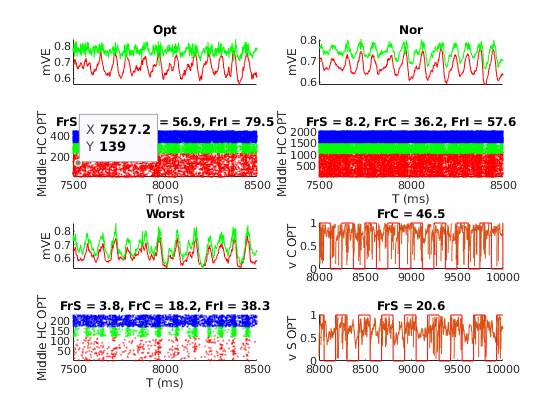

OptE = [L6SFilt>0.93*max(L6S_Drive);  L6CFilt>0.93*max(L6C_Drive)]';
OptI =  L6IFilt'>0.93*max(L6I_Drive);
WorstE = [L6SFilt<1.1*min(L6S_Drive);  L6CFilt<1.1*min(L6C_Drive)]';
WorstI =  L6IFilt'<1.1*min(L6I_Drive);
NorE = OD_E==2 | OD_E==4; NorI = OD_I==2 | OD_I==4;

MidColS = NnS.X>=1*n_S_HC & NnS.X<=2*n_S_HC;
MidRowS = NnS.Y>=1*n_S_HC & NnS.Y<=2*n_S_HC;
MidHCS = MidColS & MidRowS;
MidColC = NnC.X>=1*n_C_HC & NnC.X<=2*n_C_HC;
MidRowC = NnC.Y>=1*n_C_HC & NnC.Y<=2*n_C_HC;
MidHCC = MidColC & MidRowC;
MidHCE = [MidHCS, MidHCC];

MidColI = NnI.X>=1*n_I_HC & NnI.X<=2*n_I_HC;
MidRowI = NnI.Y>=1*n_I_HC & NnI.Y<=2*n_I_HC;
MidHCI= MidColI & MidRowI;

% SOpt = find(OptE & ~EcplxInd);
% scatterSOpt = find(ismember(SpE(:,1), SOpt));
% [~,SOpt_Ind] = ismember(SpE(scatterSOpt,1),scatterSOpt);
% FrSOpt = length(SpE(scatterSOpt,2))/(T/1e3)/length(SOpt);
%
% COpt = find(OptE & EcplxInd);
% scatterCOpt = find(ismember(SpE(:,1), COpt));
% [~,COpt_Ind] = ismember(SpE(scatterCOpt,1),scatterCOpt);
% FrCOpt = length(SpE(scatterCOpt,2))/(T/1e3)/length(COpt);

ShowWin = [7500 8500];
figure('Name','Domain Range')
OD1E = find(OptE & MidHCE);
OD1S = find(OptE & MidHCE & (~EcplxInd));
OD1C = find(OptE & MidHCE & (EcplxInd));
OD1I = find(OptI & MidHCI);
scatter1S = find(ismember(SpE(:,1),OD1S));
scatter1C = find(ismember(SpE(:,1),OD1C));
scatter1I = find(ismember(SpI(:,1),OD1I));
[~,OD1S_Ind] = ismember(SpE(scatter1S,1),OD1S);
[~,OD1C_Ind] = ismember(SpE(scatter1C,1),OD1C);
[~,OD1I_Ind] = ismember(SpI(scatter1I,1),OD1I);
subplot 423
hold on
scatter(SpE(scatter1S,2),OD1S_Ind,0.5,'r.')
scatter(SpE(scatter1C,2),OD1C_Ind+max(OD1S_Ind),0.5,'g.')
scatter(SpI(scatter1I,2),OD1I_Ind+length(OD1E),0.5,'b.');
FrS1 = length(SpE(scatter1S,2))/(T/1e3)/length(OD1S);
FrC1 = length(SpE(scatter1C,2))/(T/1e3)/length(OD1C);
FrI1 = length(SpI(scatter1I,2))/(T/1e3)/length(OD1I);
title(sprintf('FrS = %.1f, FrC = %.1f, FrI = %.1f',FrS1,FrC1,FrI1))
xlabel('T (ms)'); ylabel('Middle HC OPT')
axis tight
xlim(ShowWin)
subplot 421
hold on
plot(StatWin(1:WinNum),nanmean(mVE(OD1S,:)),'r')
plot(StatWin(1:WinNum),nanmean(mVE(OD1C,:)),'g')
ylabel('mVE')
set(gca,'xtick','')
title('Opt')
xlim(ShowWin)

OD2E = find(NorE & MidHCE);
OD2S = find(NorE & MidHCE & (~EcplxInd));
OD2C = find(NorE & MidHCE & (EcplxInd));
OD2I = find(NorI & MidHCI);
scatter2S = find(ismember(SpE(:,1),OD2S));
scatter2C = find(ismember(SpE(:,1),OD2C));
scatter2I = find(ismember(SpI(:,1),OD2I));
[~,OD2S_Ind] = ismember(SpE(scatter2S,1),OD2S);
[~,OD2C_Ind] = ismember(SpE(scatter2C,1),OD2C);
[~,OD2I_Ind] = ismember(SpI(scatter2I,1),OD2I);
subplot 424
hold on
scatter(SpE(scatter2S,2),OD2S_Ind,0.5,'r.')
scatter(SpE(scatter2C,2),OD2C_Ind+max(OD2S_Ind),0.5,'g.')
scatter(SpI(scatter2I,2),OD2I_Ind+length(OD2E),0.5,'b.');
FrS2 = length(SpE(scatter2S,2))/(T/1e3)/length(OD2S);
FrC2 = length(SpE(scatter2C,2))/(T/1e3)/length(OD2C);
FrI2 = length(SpI(scatter2I,2))/(T/1e3)/length(OD2I);
title(sprintf('FrS = %.1f, FrC = %.1f, FrI = %.1f',FrS2,FrC2,FrI2))
xlabel('T (ms)'); ylabel('Middle HC OPT')
axis tight
xlim(ShowWin)
subplot 422
hold on
plot(StatWin(1:WinNum),nanmean(mVE(OD2E,:)),'r')
plot(StatWin(1:WinNum),nanmean(mVE(OD2C,:)),'g')
ylabel('mVE')
set(gca,'xtick','')
title('Nor')
xlim(ShowWin)

OD3E = find(WorstE & MidHCE);
OD3S = find(WorstE & MidHCE & (~EcplxInd));
OD3C = find(WorstE & MidHCE & (EcplxInd));
OD3I = find(WorstI & MidHCI);
scatter3S = find(ismember(SpE(:,1),OD3S));
scatter3C = find(ismember(SpE(:,1),OD3C));
scatter3I = find(ismember(SpI(:,1),OD3I));
[~,OD3S_Ind] = ismember(SpE(scatter3S,1),OD3S);
[~,OD3C_Ind] = ismember(SpE(scatter3C,1),OD3C);
[~,OD3I_Ind] = ismember(SpI(scatter3I,1),OD3I);
subplot 427
hold on
scatter(SpE(scatter3S,2),OD3S_Ind,0.5,'r.')
scatter(SpE(scatter3C,2),OD3C_Ind+max(OD3S_Ind),0.5,'g.')
scatter(SpI(scatter3I,2),OD3I_Ind+length(OD3E),0.5,'b.');
FrS3 = length(SpE(scatter3S,2))/(T/1e3)/length(OD3S);
FrC3 = length(SpE(scatter3C,2))/(T/1e3)/length(OD3C);
FrI3 = length(SpI(scatter3I,2))/(T/1e3)/length(OD3I);
title(sprintf('FrS = %.1f, FrC = %.1f, FrI = %.1f',FrS3,FrC3,FrI3))
xlabel('T (ms)'); ylabel('Middle HC OPT')
axis tight
xlim(ShowWin)
subplot 425
hold on
plot(StatWin(1:WinNum),nanmean(mVE(OD3E,:)),'r')
plot(StatWin(1:WinNum),nanmean(mVE(OD3C,:)),'g')
ylabel('mVE')
set(gca,'xtick','')
title('Worst')
xlim(ShowWin)

% subplot 427
% hist(SpE(ismember(SpE(:,1),find(NorE & MidHCE)),2),0:1:T)
% xlabel('T (ms)'); ylabel('Spike count for all E cells')
% axis tight
% xlim(ShowWin)
% subplot 425
% plot(StatWin(1:WinNum),nanmean(mVE(OD_E'==2| OD_E'==4,:)))
% ylabel('mVE')
% set(gca,'xtick','')
% xlim(ShowWin)
tCorrect = linspace(-T,0,WinNum+1); % Use mV recording time grid
subplot 426
hold on
NeuInd = OD1C(5);
OnOff = double(~logical(floor(mod(PhaseE(NeuInd,:) + tCorrect,tMod)/MaxOnPhase)));
plot(StatWin,OnOff,'r')
plot(StatWin(1:WinNum),mVE(NeuInd,:))
xlim([8e3 10e3])
Fr1E1 = length(SpE(ismember(SpE(:,1),NeuInd),2))/(T/1e3)/1;
title(sprintf('FrC = %.1f',Fr1E1))
ylabel('v C OPT')
subplot 428
hold on
NeuInd = OD1S(1);
OnOff = double(~logical(floor(mod(PhaseE(NeuInd,:) + tCorrect,tMod)/MaxOnPhase)));
plot(StatWin,OnOff,'r')
plot(StatWin(1:WinNum),mVE(NeuInd,:))
xlim([8e3 10e3])
Fr1E2 = length(SpE(ismember(SpE(:,1),NeuInd),2))/(T/1e3)/1;
title(sprintf('FrS = %.1f',Fr1E2))
ylabel('v S OPT')

% OD_EMapTry = OD_EMap;
% OD_EMapTry([1:54,109:161],:) = 0;
% OD_EMapTry(:,[1:54,109:161]) = 0;
% OptOne = find(OD_EMapTry(:)==1);

### Plot Spatial maps: Plot

WinSize = 9000;
Window = [T-WinSize T];
EffSize = Window(2)-max(0,Window(1));


Determine On and Off t for Frs and mVs: 

Note, we get rid of the first 10ms of each interval

tCorrect = linspace(-T,0,WinNum+1); % Use mV recording time grid
PhaseExc = 20;
mVPh = mod(repmat(PhaseE, 1, WinNum) + repmat(tCorrect(1:end-1), N_E, 1), tMod);
OnOffmV = ~logical(floor(mVPh/MaxOnPhase)); % 1 for all on period, 0 for all off
OnmV  =  OnOffmV & ~(0< mVPh & mVPh<PhaseExc);
OffmV = ~OnOffmV & ~(MaxOnPhase< mVPh & mVPh<MaxOnPhase+PhaseExc);

SpPh = mod(PhaseE(SpE(:,1)) - T + SpE(:,2),tMod);
OnOffSpE =  ~logical(floor(SpPh/MaxOnPhase));
% OnSpE  =  OnOffSpE & ~(0<SpPh & SpPh<PhaseExc);
% OffSpE = ~OnOffSpE & ~(MaxOnPhase<SpPh & SpPh<MaxOnPhase+PhaseExc);
% PixelNum per HC
NPixX = 10; %10
NPixY = 10;

% NnS.X = NnE.X(~EcplxInd); NnS.Y = NnE.Y(~EcplxInd);
% NnC.X = NnE.X(EcplxInd); NnC.Y = NnE.Y(EcplxInd);

FrERan = [0 55];
mVERan = [0.62 0.80];

Figure for ONOFF

First create an onoff vec for each spike

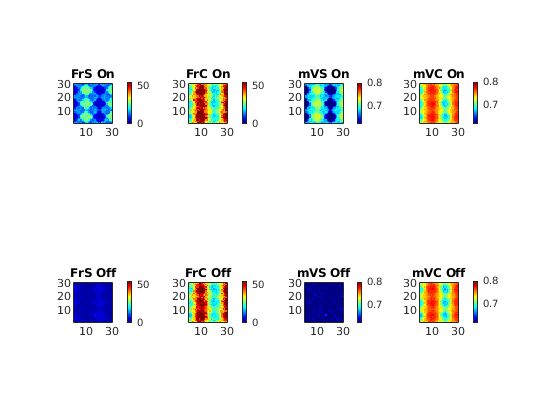

hFrVOnOff = figure('Name','Field_f&V');
% Firing rates:S
subplot 241
ESPinWinOn = SpE(:,2)>=Window(1) & SpE(:,2)<=Window(2) & OnOffSpE;
SpEGoodOn = SpE(ESPinWinOn,1);
[SpCNOn, SpCIOn] = groupcounts(SpEGoodOn);
FrEOn_temp = zeros(N_E,1);
FrEOn_temp(SpCIOn) = SpCNOn*1e3/(EffSize/2);
[FrSOnPixMat,~] = NeuVec2Pixel(FrEOn_temp(~EcplxInd),NnS,NPixX*N_HC,NPixY*N_HC);
imagesc(FrSOnPixMat); title('FrS On')
set(gca,'YDir','normal')
axis square
colormap jet; caxis(FrERan)
colorbar

subplot 245
ESPinWinOff = SpE(:,2)>=Window(1) & SpE(:,2)<=Window(2) & ~OnOffSpE;
SpEGoodOff = SpE(ESPinWinOff,1);
[SpCNOff, SpCIOff] = groupcounts(SpEGoodOff);
FrEOff_temp = zeros(N_E,1);
FrEOff_temp(SpCIOff) = SpCNOff*1e3/(EffSize/2);
[FrSOffPixMat,~] = NeuVec2Pixel(FrEOff_temp(~EcplxInd),NnS,NPixX*N_HC,NPixY*N_HC);
imagesc(FrSOffPixMat); title('FrS Off')
set(gca,'YDir','normal')
axis square
colormap jet ; caxis(FrERan)
colorbar

% Firing rates: C
subplot 242
[FrCOnPixMat,~] = NeuVec2Pixel(FrEOn_temp(EcplxInd),NnC,NPixX*N_HC,NPixY*N_HC);
imagesc(FrCOnPixMat); title('FrC On')
set(gca,'YDir','normal')
axis square
colormap jet; caxis(FrERan)
colorbar

subplot 246
[FrCOffPixMat,~] = NeuVec2Pixel(FrEOff_temp(EcplxInd),NnC,NPixX*N_HC,NPixY*N_HC);
imagesc(FrCOffPixMat); title('FrC Off')
set(gca,'YDir','normal')
axis square
colormap jet ; caxis(FrERan)
colorbar

Win2Col = floor((Window)/(T/size(mVE,2)));
SmallWinRange = Win2Col(1):Win2Col(2);
% mVs: S
OnmVPhase = double(OnmV);
OnmVPhase(~OnmV) = nan;
mVEOn = mVE; mVEOn = mVEOn.*OnmVPhase;
mVEOn_temp = nanmean(mVEOn(:,SmallWinRange),2);

subplot 243
[mVSOnPixMat,~] = NeuVec2Pixel(mVEOn_temp(~EcplxInd),NnS,NPixX*N_HC,NPixY*N_HC);
imagesc(mVSOnPixMat); title('mVS On')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; caxis(mVERan)

OffmVPhase = double(OffmV);
OffmVPhase(~OffmV) = nan;
mVEOff = mVE; mVEOff = mVEOff.*OffmVPhase;
mVEOff_temp = nanmean(mVEOff(:,SmallWinRange),2);

subplot 247
[mVSOffPixMat,~] = NeuVec2Pixel(mVEOff_temp(~EcplxInd),NnS,NPixX*N_HC,NPixY*N_HC);
imagesc(mVSOffPixMat); title('mVS Off')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; caxis(mVERan)

% mVs: C
subplot 244
[mVCOnPixMat,~] = NeuVec2Pixel(mVEOn_temp(EcplxInd),NnC,NPixX*N_HC,NPixY*N_HC);
imagesc(mVCOnPixMat); title('mVC On')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; caxis(mVERan)

subplot 248
[mVCOffPixMat,~] = NeuVec2Pixel(mVEOff_temp(EcplxInd),NnC,NPixX*N_HC,NPixY*N_HC);
imagesc(mVCOffPixMat); title('mVC Off')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; caxis(mVERan)

Figure for All Average

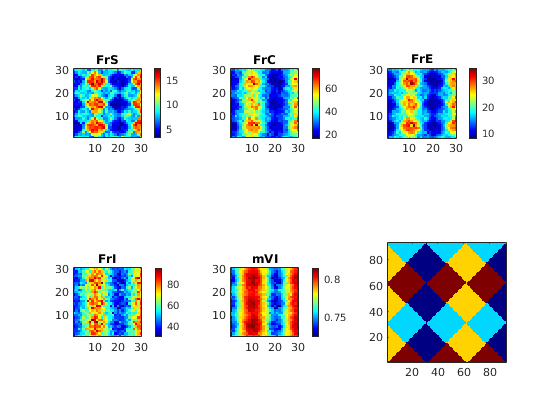

hFrVAll = figure('Name','Field_f&V');
ESPinWin = SpE(:,2)>=Window(1) & SpE(:,2)<=Window(2);
SpEGood = SpE(ESPinWin,1);
[SpCN, SpCI] = groupcounts(SpEGood);
FrE_temp = zeros(N_E,1);
FrE_temp(SpCI) = SpCN*1e3/(EffSize);
%FrE_Map = reshape(FrE_temp,N_HC*n_E_HC,N_HC*n_E_HC); % not used here

subplot 231
[FrSPixMat,NnSPixel] = NeuVec2Pixel(FrE_temp(~EcplxInd),NnS,NPixX*N_HC,NPixY*N_HC);
imagesc(FrSPixMat); title('FrS')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar
subplot 232
[FrCPixMat,NnCPixel] = NeuVec2Pixel(FrE_temp(EcplxInd),NnC,NPixX*N_HC,NPixY*N_HC);
imagesc(FrCPixMat); title('FrC')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

subplot 233
imagesc(FrSPixMat*(1-CplxR)+ FrCPixMat*CplxR);
title('FrE')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

subplot 234
ISPinWin = (SpI(:,2)>=Window(1) & SpI(:,2)<=Window(2));
SpIGood = SpI(ISPinWin,1);
[SpCN, SpCI] = groupcounts(SpIGood);
FrI_temp = zeros(N_I,1);
FrI_temp(SpCI) = SpCN*1e3/EffSize;
FrI_Map = reshape(FrI_temp,N_HC*n_I_HC,N_HC*n_I_HC);

[FrIPixMat,NnIPixel] = NeuVec2Pixel(FrI_temp,NnI,NPixX*N_HC,NPixY*N_HC);
imagesc(FrIPixMat); title('FrI')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

Win2Col = floor((Window)/(T/size(mVE,2)));
SmallWinRange = Win2Col(1):Win2Col(2);
subplot 235
mVI_temp = nanmean(mVI(:,SmallWinRange),2);
mVI_Map = reshape(mVI_temp,N_HC*n_I_HC,N_HC*n_I_HC);

[mVIPixMat,~] = NeuVec2Pixel(mVI_temp,NnI,NPixX*N_HC,NPixY*N_HC);
imagesc(mVIPixMat); title('mVI')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

% Orientation domain
% subplot 233
% imagesc(OD_EMap);axis square
% set(gca,'YDir','normal')

subplot 236
imagesc(OD_IMap);axis square
set(gca,'YDir','normal')

Complex % Simple spikes

% end of 500ms plot
OPTC = find(OD_E == 1 & EcplxInd);
OPTS = find(OD_E == 1 & ~EcplxInd);
WORST = find(OD_E == 3);
MID = find(OD_E == 2 | OD_E == 4);
hSpCount = figure('Name','SpCountE')

hSpCount =   Figure (18: SpCountE) with properties:

      Number: 18
        Name: 'SpCountE'
       Color: [0.9400 0.9400 0.9400]
    Position: [1761 1399 560 420]
       Units: 'pixels'

  Show all properties


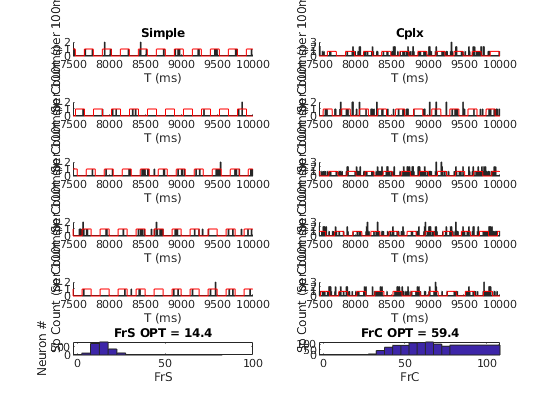

USE = [1,50,300,1000 1500];
for subInd = 1:5
    subplot(6,2,2*subInd-1)
    NeuInd = OPTS(USE(subInd));
    hold on
    hist(SpE(ismember(SpE(:,1),NeuInd),2),0:10:T)
    OnOff = double(~logical(floor(mod(PhaseE(NeuInd) + tCorrect(1:end-1),tMod)/MaxOnPhase)));
    plot(StatWin(1:WinNum),OnOff,'r')
    xlim([T-T/LGNFreq T])
    xlabel('T (ms)')
    ylabel('Sp Count (per 100ms)')
    if subInd ==1
        title('Simple')
    end

    subplot(6,2,2*subInd)
    NeuInd = OPTC(USE(subInd));
    hold on
    hist(SpE(ismember(SpE(:,1),NeuInd),2),0:10:T)
    OnOff = double(~logical(floor(mod(PhaseE(NeuInd) + tCorrect(1:end-1),tMod)/MaxOnPhase)));
    plot(StatWin(1:WinNum),OnOff,'r')
    xlim([T-T/LGNFreq T])
    xlabel('T (ms)')
    ylabel('Sp Count (per 100ms)')

    if subInd ==1
        title('Cplx')
    end

end
OPTS = OptE & ~EcplxInd;
OPTC = OptE & EcplxInd;
subplot(6,2,11)
hist(FrE_temp(OPTS),0:5:80)
title(sprintf('FrS OPT = %.1f', mean(FrE_temp(OPTS))))
xlabel('FrS'); ylabel('Neuron #')
subplot(6,2,12)
hist(FrE_temp(OPTC),0:5:80)
title(sprintf('FrC OPT = %.1f', mean(FrE_temp(OPTC))))
xlabel('FrC')

%save('DriveWkSp.mat')

### A5. MF linear equation for pixels: 1 Matrices

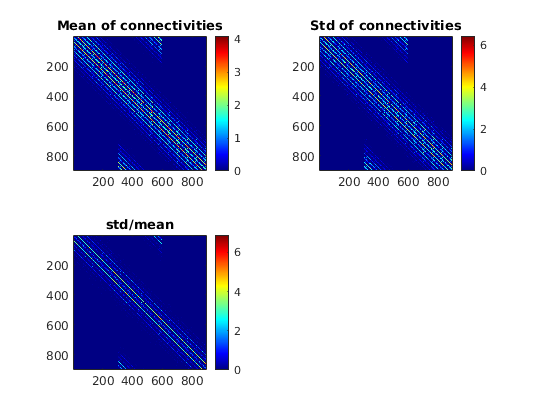

clear ESPinWin ESPinWinOn ESPinWinOff ISPinWin...
    OffmVPhase OnmVPhase OnOffmV OnOffSpE...
    SpE SpECurrent SpEGood SpEGoodOff SpEGoodOn SpI SpICurrent SpIGood...
    mVE mVEOff mVEOn mVI

load(['ConnPixel_Cconst.mat'])
% Present connectivity mats
figure
subplot 221
imagesc(C_SS_Pixel_Us)
colormap jet
colorbar
axis square
title('Mean of connectivities')
subplot 222
imagesc(C_CS_Pixel_Us)
axis square
colorbar
title('Std of connectivities')
subplot 223
imagesc(C_CI_Pixel_Us)
axis square
colorbar
title('std/mean')


PixNum = NPixX*N_HC * NPixY*N_HC;
FrSPixVec    = reshape(FrSPixMat,  PixNum,1);
FrSOnPixVec  = reshape(FrSOnPixMat,PixNum,1);
FrSOffPixVec = reshape(FrSOffPixMat,PixNum,1);
FrCPixVec    = reshape(FrCPixMat,  PixNum,1);
FrCOnPixVec  = reshape(FrCOnPixMat,PixNum,1);
FrCOffPixVec = reshape(FrCOffPixMat,PixNum,1);
FrIPixVec    = reshape(FrIPixMat,  PixNum,1);

mVSOnPixVec  = reshape(mVSOnPixMat,PixNum,1);
mVSOffPixVec = reshape(mVSOffPixMat,PixNum,1);
mVCOnPixVec  = reshape(mVCOnPixMat,PixNum,1);
mVCOffPixVec = reshape(mVCOffPixMat,PixNum,1);
mVIPixVec = reshape(mVIPixMat,PixNum,1);

% Precompute LGN and L6
lambda_SOn_Pixel = zeros(PixNum,1);
lambda_SOff_Pixel = zeros(PixNum,1);
lambda_COn_Pixel = zeros(PixNum,1);
lambda_COff_Pixel = zeros(PixNum,1);
L6S_Pixel = zeros(PixNum,1);
L6C_Pixel = zeros(PixNum,1);
L6I_Pixel = zeros(PixNum,1);
lambda_SOn_drive = lambda_EOn_drive(~EcplxInd); lambda_COn_drive = lambda_EOn_drive(EcplxInd);
lambda_SOff_drive = lambda_EOff_drive(~EcplxInd); lambda_COff_drive = lambda_EOff_drive(EcplxInd);
rS_L6_Drive = rE_L6_Drive(~EcplxInd); rC_L6_Drive = rE_L6_Drive(EcplxInd);
for PixInd = 1:PixNum
    lambda_SOn_Pixel(PixInd)  = mean(lambda_SOn_drive(NnSPixel.Vec == PixInd));
    lambda_SOff_Pixel(PixInd) = mean(lambda_SOff_drive(NnSPixel.Vec == PixInd));
    lambda_COn_Pixel(PixInd)  = mean(lambda_COn_drive(NnCPixel.Vec == PixInd));
    lambda_COff_Pixel(PixInd) = mean(lambda_COff_drive(NnCPixel.Vec == PixInd));
    L6S_Pixel(PixInd) = mean(rS_L6_Drive(NnSPixel.Vec == PixInd));
    L6C_Pixel(PixInd) = mean(rC_L6_Drive(NnCPixel.Vec == PixInd));
    L6I_Pixel(PixInd) = mean(rI_L6_Drive(NnIPixel.Vec == PixInd));
end
lambda_I_Pixel = lambda_I_drive_Pre;

Below need work

% Setup preused Firing rates for off E
%FrPreUseDim = find(lambda_EOff_Pixel<0.08) + PixNum;
FrPreUseDim = (1:PixNum) + 2*PixNum;
FrPreUse = FrSOffPixVec(FrPreUseDim - 2*PixNum);
%FrPreUse = FrEOffLIF(FrPreUseDim - PixNum);
FrPreUse = [];

### A6. Clear redundant variables for memory

clear C_EE C_EE_Fix_Bd C_EI C_EI_Fix_Bd...
    C_IE C_IE_Fix_Bd C_II C_II_Fix_Bd...
    C_SS_Fix_Bd C_SC_Fix_Bd C_CS_Fix_Bd C_CC_Fix_Bd...
    C_SI_Fix_Bd C_CI_Fix_Bd C_IS_Fix_Bd C_IC_Fix_Bd...
    COpt_Ind SOpt_Ind scatterCOpt scatterSOpt...
    ESPinWin ESPinWinOn ESPinWinOff ISPinWin...
    OffmVPhase OnmVPhase OnOffmV OnOffSpE OnmV OffmV...
    SpE SpECurrent SpEGood SpEGoodOff SpEGoodOn SpI SpICurrent SpIGood SpPh...
    mVE mVEOff mVEOn mVI ...
    NWTrace AmbE_Events AdjlgnE AmbI_Events CMatAll ...
    EampaInp EnmdaInp GE_ETemp GE_ITemp IampaInp InmdaInp ...
    L6E_Events L6I_Events lgnE_Events lgnI_Events...
    mVECurrent mVICurrent mVETemp mVPh
save([SaveFolder,'AllMFPixPara_Paper2TuneFig1V4D2.mat'])